# SNW_DS_MAIN More Dense Solution Analysis

This is the example vignette for function: [**snw_ds_main**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/params/snw_ds_main.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for vfi and gets distribution induced by policy functions and exogenous distributions.More Dense Simulation.  **Looped** to get distribution, but uses **bisect vec** for VFI.

## Test SNW_DS_MAIN Defaults More Dense

Call the function with testing defaults.

mp_params = snw_mp_param('default_moredense');
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_vfi') = false;
mp_controls('bl_print_ds') = false;
mp_controls('bl_print_ds_verbose') = false;
[Phi_true,Phi_adj,A_agg,Y_inc_agg,it,mp_dsvfi_results] = snw_ds_main(mp_params, mp_controls);

Elapsed time is 232.238296 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=default_moredense;SNW_MP_CONTROL=default_test
Elapsed time is 568.244072 seconds.
Completed SNW_DS_MAIN;SNW_MP_PARAM=;default_moredense;SNW_MP_CONTROL=;default_test


Phi_true = Phi_true/sum(Phi_true(:));

## Show All Info in mp_dsvfi_results More Dense

mp_cl_mt_xyz_of_s = mp_dsvfi_results('mp_cl_mt_xyz_of_s');
disp(mp_cl_mt_xyz_of_s('tb_outcomes'))

                       mean         sd       coefofvar      min         max       pYis0      pYls0      pYgr0      pYisMINY      pYisMAXY      p0_01        p0_1        p1          p5         p10         p20          p25          p30         p40         p50         p60         p70        p75         p80         p90        p95        p99       p99_9     p99_99     fl_cov_a_ss    fl_cor_a_ss    fl_cov_ap_ss    fl_cor_ap_ss    fl_c

## More Dense Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Probability mass matrixes, Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = 18:100;
agrid = mp_params('agrid')';
eta_H_grid = mp_params('eta_H_grid')';
eta_S_grid = mp_params('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'eta', 1:length(eta_H_grid)});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Probability Mass Along Age Dimensions

Where are the mass at? Analyze mass given state space components.

% Get the Joint distribution over all states
% Define Graph Inputs
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log

#### Exogenous Permanent States Mass: Life Cycle, Edu and Marraige

Tabulate value and policies along savings and shocks:

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,5,4];
% Value Function
tb_prob_aem = ff_summ_nd_array("P(Age, EDU, MARRY))", Phi_true, true, ["sum"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, EDU, MARRY))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    marry    edu    sum_age_18    sum_age_19    sum_age_20    sum_age_21    sum_age_22    sum_age_23    sum_age_24    sum_age_25    sum_age_26    sum_age_27    sum_age_28    sum_age_29    sum_age_30    sum_age_31    sum_age_32    sum_age_33    sum_age_34    sum_age_35    sum_age_36    sum_age_37    sum_age_38    sum_age_39    sum_age_40    sum_age_41    sum_age_42    sum_age_43    sum_age_44    sum_age_45  

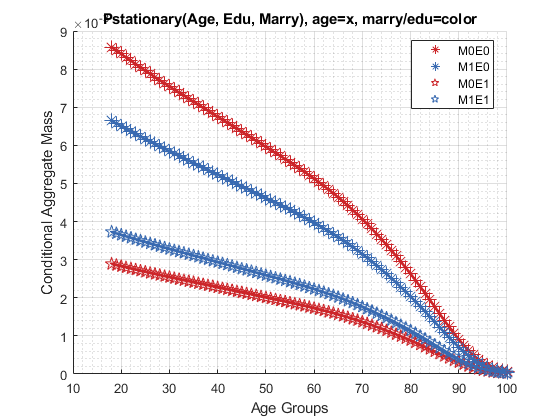

mp_support_graph('cl_st_graph_title') = {'Pstationary(Age, Edu, Marry), age=x, marry/edu=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = ["M0E0", "M1E0", "M0E1", "M1E1"];
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
mp_support_graph('cl_scatter_shapes') = {'*', '*', 'p', 'p' };
mp_support_graph('cl_colors') = {'red', 'blue', 'red', 'blue'};
ff_graph_grid((tb_prob_aem{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

#### Kids and Marry By Age Mass

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_prob_amarrykids = ff_summ_nd_array("P(Age, Kids, Marry))", Phi_true, true, ["sum"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, Kids, Marry))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    sum_age_18    sum_age_19    sum_age_20    sum_age_21    sum_age_22    sum_age_23    sum_age_24    sum_age_25    sum_age_26    sum_age_27    sum_age_28    sum_age_29    sum_age_30    sum_age_31    sum_age_32    sum_age_33    sum_age_34    sum_age_35    sum_age_36    sum_age_37    sum_age_38    sum_age_39    sum_age_40    sum_age_41    sum_age_42    sum_age_43    sum_age_44    sum_age_45

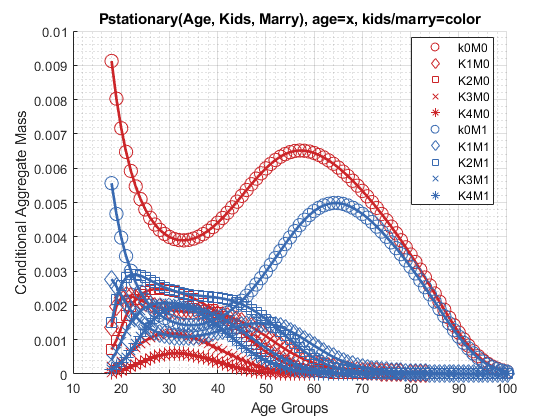

mp_support_graph('cl_st_graph_title') = {'Pstationary(Age, Kids, Marry), age=x, kids/marry=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = [...
    "k0M0", "K1M0", "K2M0", "K3M0", "K4M0", ...
    "k0M1", "K1M1", "K2M1", "K3M1", "K4M1"];
mp_support_graph('cl_scatter_shapes') = {...
    'o', 'd' ,'s', 'x', '*', ...
    'o', 'd', 's', 'x', '*'};
mp_support_graph('cl_colors') = {...
    'red', 'red', 'red', 'red', 'red'...
    'blue', 'blue', 'blue', 'blue', 'blue'};
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
ff_graph_grid((tb_prob_amarrykids{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Probability Mass Asset and Shock Dimensions

Where are the mass at?

% Define Graph Inputs
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log

#### Asset and Shock Mass

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_prob_az = ff_summ_nd_array("P(A,Z))", Phi_true, true, ["sum"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings      sum_eta_1     sum_eta_2     sum_eta_3     sum_eta_4     sum_eta_5     sum_eta_6     sum_eta_7     sum_eta_8     sum_eta_9     sum_eta_10    sum_eta_11    sum_eta_12    sum_eta_13    sum_eta_14    sum_eta_15    sum_eta_16    sum_eta_17    sum_eta_18    sum_eta_19    sum_eta_20    sum_eta_21    sum_eta_22    sum_eta_23    sum_eta_24    sum_eta_25    sum_eta_26    sum_eta_27    sum_eta_28    sum_eta_29  

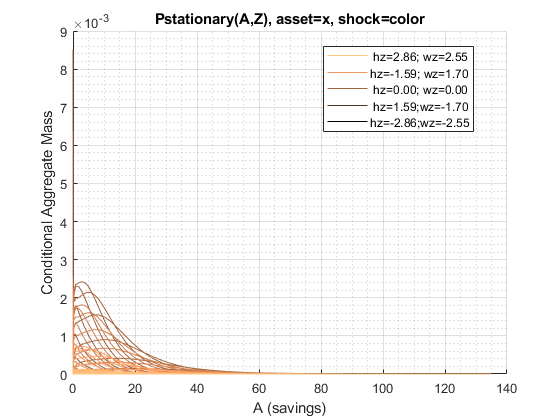

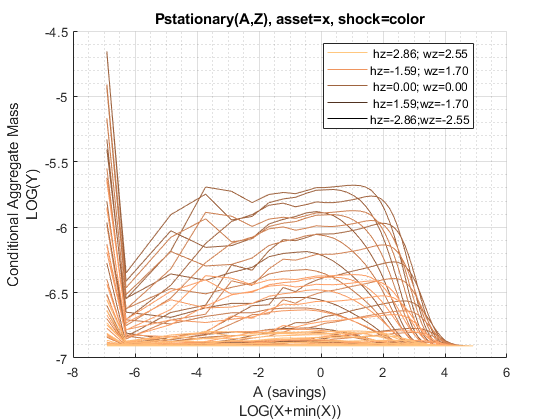

mp_support_graph('cl_st_graph_title') = {'Pstationary(A,Z), asset=x, shock=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'A (savings)'};
mp_support_graph('st_rowvar_name') = 'z=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.2f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
ff_graph_grid((tb_prob_az{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);% Consumption Choices

#### Asset Mass by Age

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [3,4,5,6,1,2];
% Value Function
tb_prob_aage = ff_summ_nd_array("P(A,Z))", Phi_true, true, ["sum"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings      sum_age_18    sum_age_19    sum_age_20    sum_age_21    sum_age_22    sum_age_23    sum_age_24    sum_age_25    sum_age_26    sum_age_27    sum_age_28    sum_age_29    sum_age_30    sum_age_31    sum_age_32    sum_age_33    sum_age_34    sum_age_35    sum_age_36    sum_age_37    sum_age_38    sum_age_39    sum_age_40    sum_age_41    sum_age_42    sum_age_43    sum_age_44    sum_age_45    sum_age_46  

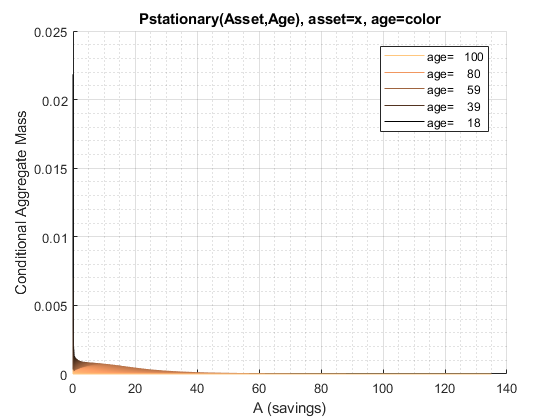

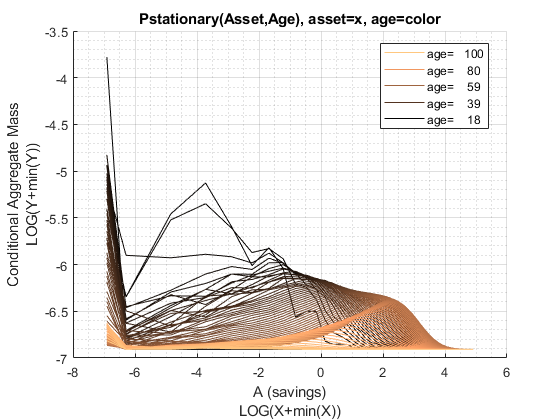

mp_support_graph('cl_st_graph_title') = {'Pstationary(Asset,Age), asset=x, age=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'A (savings)'};
mp_support_graph('st_rowvar_name') = 'age=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.0f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
ff_graph_grid((tb_prob_aage{1:end, 3:end})', age_grid, agrid, mp_support_graph);% Consumption Choices

## Probability Statistics A, C and V Conditional on Ages

Where are the mass at?

ap_ss = mp_dsvfi_results('ap_ss');
c_ss = mp_dsvfi_results('cons_ss');
v_ss = mp_dsvfi_results('v_ss');
n_ss = mp_dsvfi_results('n_ss');

y_head_inc = mp_dsvfi_results('y_head_inc_ss');
y_spouse_inc = mp_dsvfi_results('y_spouse_inc_ss');

yshr_wage = mp_dsvfi_results('yshr_wage_ss');
yshr_SS = mp_dsvfi_results('yshr_SS_ss');
yshr_nttxss = mp_dsvfi_results('yshr_nttxss_ss');

for it_ctr=1:size(ap_ss, 1)
    if (ismember(it_ctr, round(linspace(1, size(ap_ss, 1), 3))))
        display(['age =' num2str(age_grid(it_ctr))]);
        
        % construct input data
        Phi_true_age = Phi_true(it_ctr, :, :, : ,: ,:);
        ap_ss_age = ap_ss(it_ctr, :, :, : ,: ,:);
        c_ss_age = c_ss(it_ctr, :, :, : ,: ,:);
        v_ss_age = v_ss(it_ctr, :, :, : ,: ,:);
        n_ss_age = n_ss(it_ctr, :, :, : ,: ,:);

        y_head_inc_age = y_head_inc(it_ctr, :, :, : ,: ,:);
        y_spouse_inc_age = y_spouse_inc(it_ctr, :, :, : ,: ,:);
        yshr_wage_age = yshr_wage(it_ctr, :, :, : ,: ,:);
        yshr_SS_age = yshr_SS(it_ctr, :, :, : ,: ,:);
        yshr_nttxss_age = yshr_nttxss(it_ctr, :, :, : ,: ,:);
        
        mp_cl_ar_xyz_of_s = containers.Map('KeyType','char', 'ValueType','any');
        mp_cl_ar_xyz_of_s('ap_ss') = {ap_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('c_ss') = {c_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('v_ss') = {v_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('n_ss') = {n_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('y_head_inc') = {y_head_inc_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('y_spouse') = {y_spouse_inc_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('yshr_wage') = {yshr_wage_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('yshr_SS') = {yshr_SS_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('yshr_nttxss') = {yshr_nttxss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('ar_st_y_name') = ["ap_ss", "c_ss", "v_ss", "n_ss",...
            "y_head_inc", "y_spouse", "yshr_wage", "yshr_SS", "yshr_nttxss"];
        
        % controls
        mp_support = containers.Map('KeyType','char', 'ValueType','any');
        mp_support('ar_fl_percentiles') = [0.01 10 25 50 75 90 99.99];
        mp_support('bl_display_final') = true;
        mp_support('bl_display_detail') = false;    
        mp_support('bl_display_drvm2outcomes') = false;  
        mp_support('bl_display_drvstats') = false;
        mp_support('bl_display_drvm2covcor') = false;
    
        % Call Function     
        mp_cl_mt_xyz_of_s = ff_simu_stats(Phi_true_age(:)/sum(Phi_true_age,'all'), mp_cl_ar_xyz_of_s, mp_support);
    end
end

age =18
xxx tb_outcomes: all stats xxx
    OriginalVariableNames        ap_ss          c_ss           v_ss          n_ss        y_head_inc      y_spouse       yshr_wage     yshr_SS    yshr_nttxss
    ______________________    ___________    ___________    __________    ___________    ___________    ___________    ___________    _______    ___________

    {'mean'              }        0.12094        0.72571        -23.84         1.9854        0.83951        0.20898              1        0          0.17269
    {'sd'                }        0.25634        0.42617        24.381         1.0848        0.62548        0.43796     6.6613e-16        0         0